# EAS4305/6305 read excel from BATS

The goal of this homework is to experience getting oceanographic dataset from a ocean time series station. This script helps with the first 2 steps of the HW1.

% safety first
close all
clear all

% Step 1 download data from BATS and create data vectors
data=xlsread('b10331_ctd.xls');
castid=data(:,1);
lat=data(:,4);
lon=-data(:,5); % the data in in deg W so it should be negative
dep=data(:,6);
p=data(:,7);
t=data(:,8);
sp=data(:,10);

% TEOS-10 calculations
SA=gsw_SA_from_SP(sp,p,lon,lat);
CT=gsw_CT_from_t(SA,t,p);

% define X and Y axes of the T-S diagram
x=linspace(min(SA),max(SA),100);
y=linspace(min(CT),max(CT),101);
[xx,yy]=meshgrid(x,y);

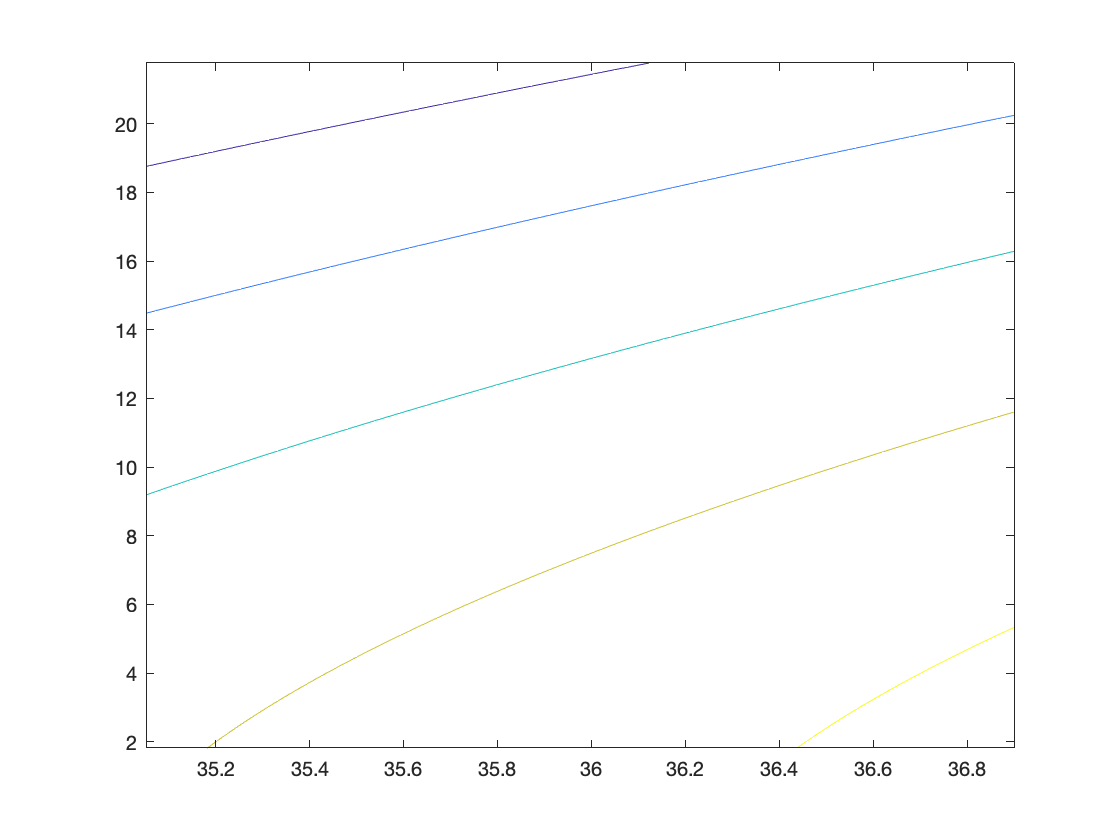

% create sigma-theta array
sig0=gsw_sigma0(xx,yy);
% plot the density contours
figure(1);
contour(xx,yy,sig0,22:1:29);



% Step 2 select cast 2
ca = (castid==10331002);
p2=p(ca); % p2 contains pressure from cast 2 only
t2=t(ca); % t2 contains temperature from cast 2
